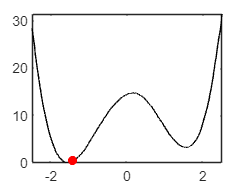

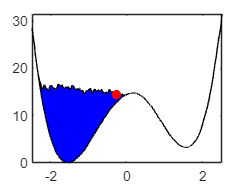

cv=[-2.52456 -2.47734 -2.45625 -2.43517 -2.41999 -2.40396 -2.38457 -2.35927 -2.34156 -2.31288 -2.29602 -2.26987 -2.24626 -2.21843 -2.19144 -2.15686 -2.12482 -2.08939 -2.05566 -2.01012 -1.96795 -1.90301 -1.8541 -1.74784 -1.65929 -1.54797 -1.4611 -1.35906 -1.21484 -1.14147 -1.03521 -0.976175 -0.883407 -0.803289 -0.713894 -0.646426 -0.598355 -0.536791 -0.477757 -0.419566 -0.349568 -0.271136 -0.210415 -0.122707 -0.0223487 0.0754797 0.168248 0.28463 0.350411 0.45077 0.526671 0.572212 0.611849 0.659077 0.714738 0.759435 0.820999 0.885094 0.946658 0.991356 1.05714 1.11111 1.16677 1.24689 1.29243 1.3346 1.38351 1.49568 1.55893 1.63989 1.68712 1.76808 1.82205 1.8735 1.92073 1.95362 1.98145 2.00928 2.03458 2.06409 2.0953 2.12229 2.14 2.16445 2.17963 2.19987 2.22096 2.23782 2.25216 2.27156 2.28252 2.2977 2.31373 2.33144 2.34577 2.3618 2.37107 2.38794 2.40312 2.42167 2.43601 2.45541];
FES=[28.4791 27.2624 26.0393 24.9303 23.5615 22.4778 21.3371 19.8986 18.9354 17.4525 16.4956 15.2028 13.9354 12.6806 11.5906 10.2725 9.12548 7.85805 6.71103 5.44994 4.44233 3.04816 2.14195 0.931559 0.291508 0.0380228 0.215463 0.716096 1.81876 2.49049 3.82763 4.61977 5.8365 6.86312 8.0545 8.84664 9.46134 10.1838 10.9569 11.5526 12.161 12.8264 13.3333 13.9417 14.4233 14.7148 14.8352 14.6198 14.3156 13.7262 13.0418 12.5982 12.2497 11.8314 11.0583 10.5513 9.71483 8.92902 8.25729 7.62357 6.8251 6.14068 5.55133 4.85425 4.44233 4.05577 3.7706 3.33967 3.29531 3.51077 3.70722 4.35361 4.96831 5.69075 6.5019 7.26236 8.02281 8.86565 9.56274 10.3612 11.2294 12.1103 12.7503 13.6502 14.3916 15.1584 16.0646 16.9138 17.5919 18.4601 19.2142 20.0063 20.9062 21.7744 22.4398 23.3523 23.9734 24.8796 25.7605 26.6477 27.275 28.2066];
x=-2.5:0.001:2.5;
y=interp1(cv,FES,x,'spline');
hold off;
for i=1:1650
    %tic
    results=sumhills(bck,x,i );
    plot(x,y,'k-',x,y+results,'b-');
    hold on;
    fill([x,fliplr(x)],[y,fliplr(y+results)],'b')
    nowy=sumhills(bck,bck(i ,2)-1,i );
    plot(bck(i ,2)-1,nowy+interp1(cv,FES,bck(i ,2)-1,'spline'),'ro','MarkerSize',5,'MarkerFaceColor','r');
    hold off;
    name=num2str(i);
    saveas(gcf, name, 'png');
    %toc
end

for j=1:1650
    file=[num2str(j) '.png'];
    A=imread(file);
    [I,map]=rgb2ind(A,256);
    if(j==1)
        imwrite(I,map,'CVHD_slow.gif','DelayTime',0.1,'LoopCount',Inf)
    else
        imwrite(I,map,'CVHD_slow.gif','WriteMode','append','DelayTime',0.1)    
    end
end